AUDIO ANDRÉS

Letra A

%[aA,aA_Fs] = audioread('‎⁨A_a.wav');

Letra E

[eA,eA_Fs] = audioread('A_e.wav');

Letra I

[iA,iA_Fs] = audioread('A_i.wav');

Letra O

[oA,oA_Fs] = audioread('A_o.wav');

Letra U

[uA,uA_Fs] = audioread('A_u.wav');

AUDIO LORENA

Letra A

[aL,aL_Fs] = audioread('aLore.wav');

Letra E

[eL,eL_Fs] = audioread('eLore.wav');

Letra I

[iL,iL_Fs] = audioread('iLore.wav');

Letra O

[oL,oL_Fs] = audioread('oLore.wav');

Letra U

[uL,uL_Fs] = audioread('uLore.wav');  

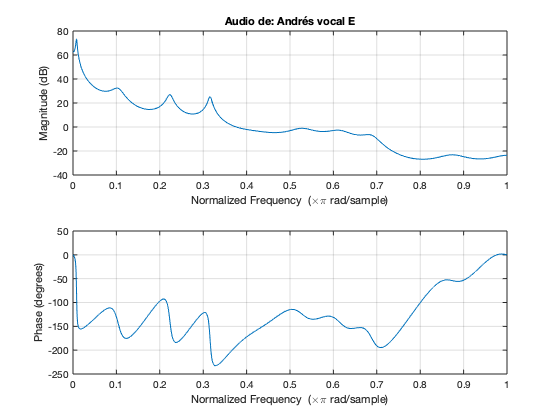

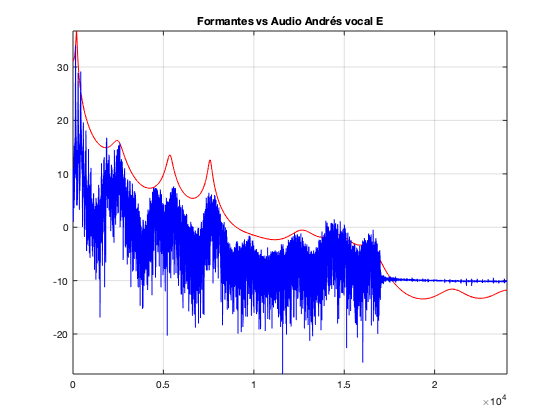

Formantes = 	1.0e+04 *

    1.6526    1.4745    1.2667    0.7580    0.5357    0.2500    0.0196


%[Formantes] = Practica8(aA,aA_Fs, ' Andrés vocal A')
[Formantes] = Practica8(eA,eA_Fs, ' Andrés vocal E')

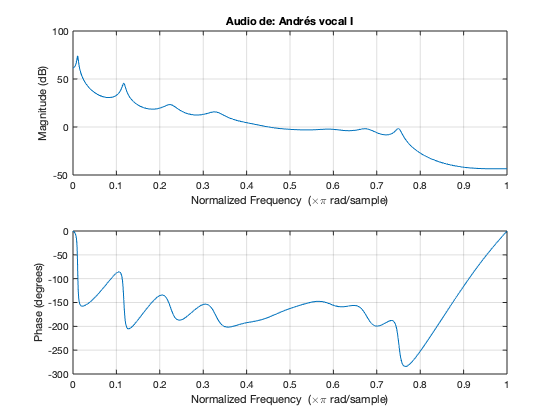

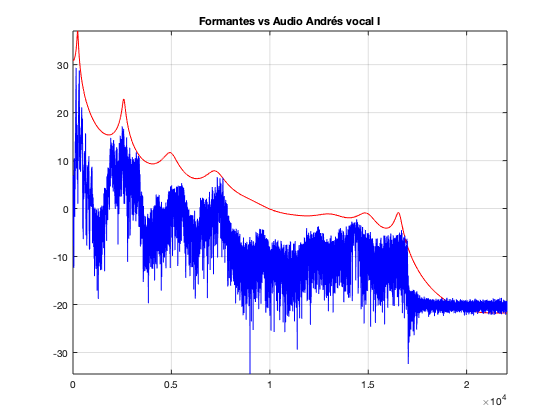

Formantes = 	1.0e+04 *

    1.6552    1.4931    0.7238    0.4953    0.2581    0.0237


[Formantes] = Practica8(iA,iA_Fs, ' Andrés vocal I')

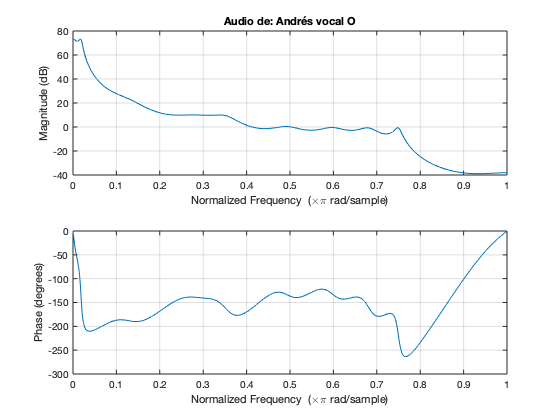

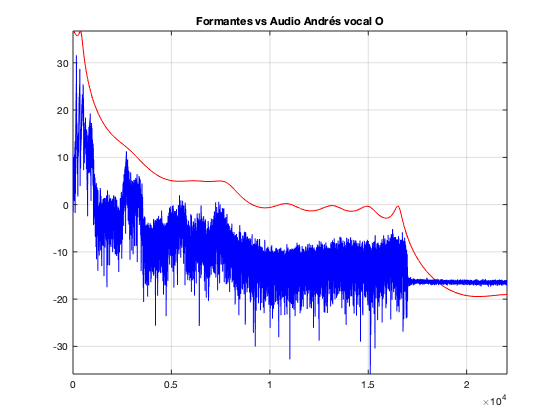

Formantes = 	1.0e+04 *

    1.6534    1.5009    1.3173    1.0877    0.7773    0.0406


[Formantes] = Practica8(oA,oA_Fs, ' Andrés vocal O')

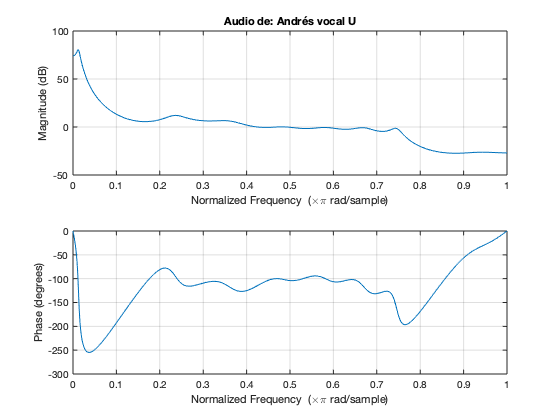

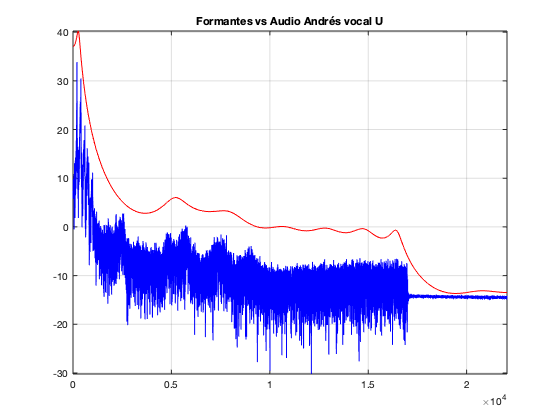

Formantes = 	1.0e+04 *

    1.6442    1.4781    1.2855    0.5189    0.0286    0.0280


[Formantes] = Practica8(uA,uA_Fs, ' Andrés vocal U')

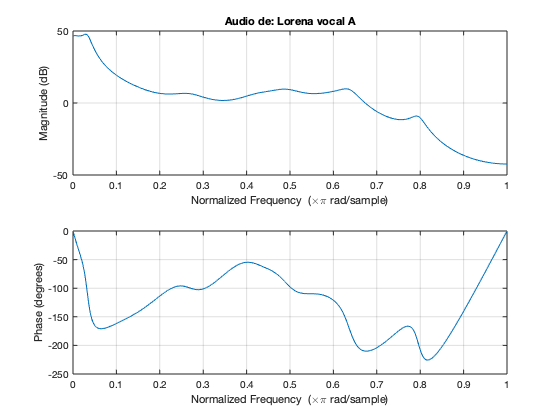

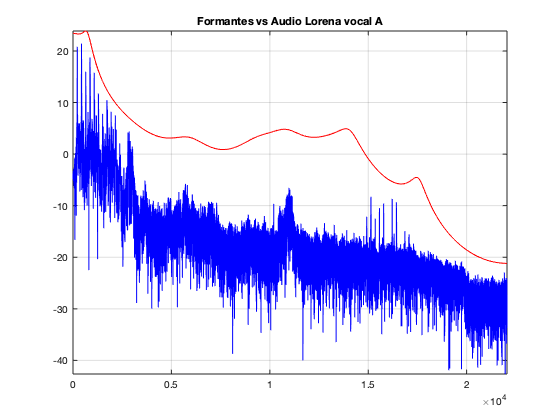

Formantes = 	1.0e+04 *

    1.7546    1.4038    0.0729


[Formantes] = Practica8(aL,aL_Fs, ' Lorena vocal A')

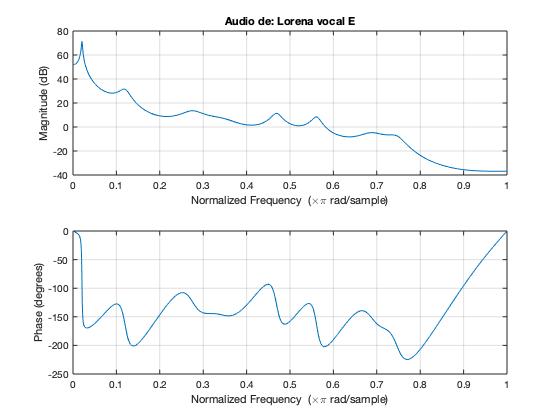

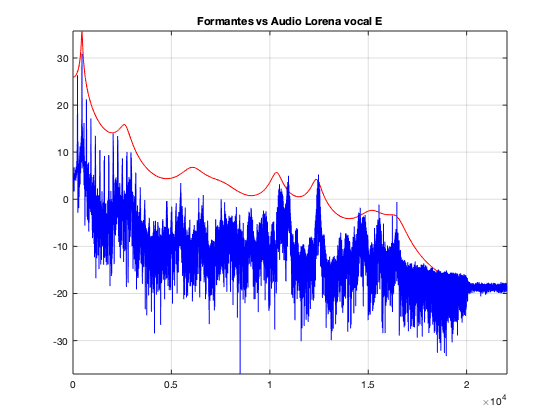

Formantes = 	1.0e+04 *

    1.6470    1.5160    1.2379    1.0340    0.6061    0.2649    0.0455


[Formantes] = Practica8(eL,eL_Fs, ' Lorena vocal E')

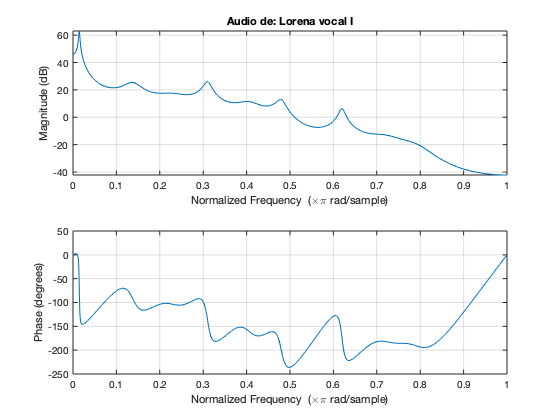

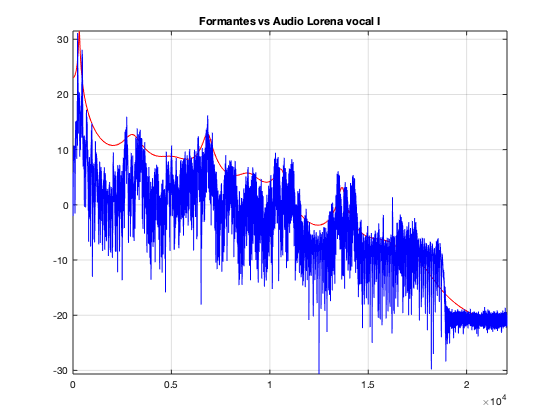

Formantes = 	1.0e+04 *

    1.3667    1.0581    0.8948    0.6838    0.3037    0.0320


[Formantes] = Practica8(iL,iL_Fs, ' Lorena vocal I')

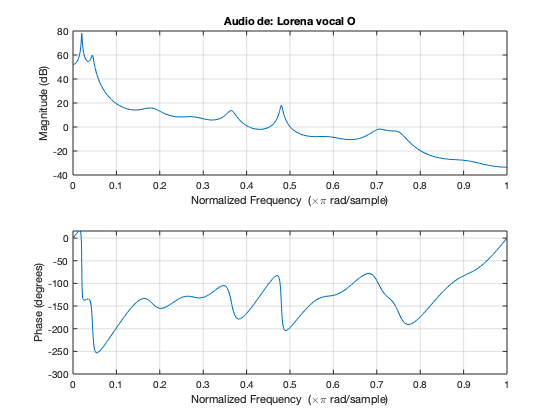

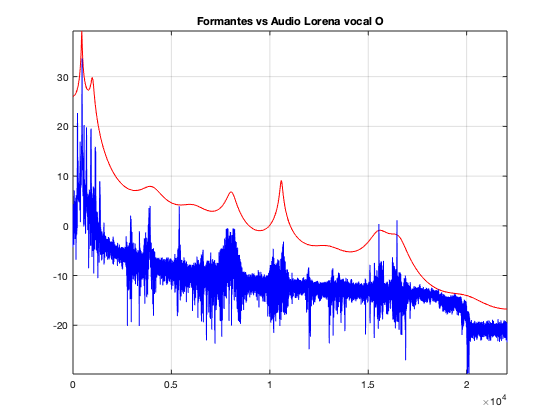

Formantes = 	1.0e+04 *

    1.6561    1.5521    1.0585    0.8050    0.6132    0.4014    0.0993    0.0446


[Formantes] = Practica8(oL,oL_Fs, ' Lorena vocal O')

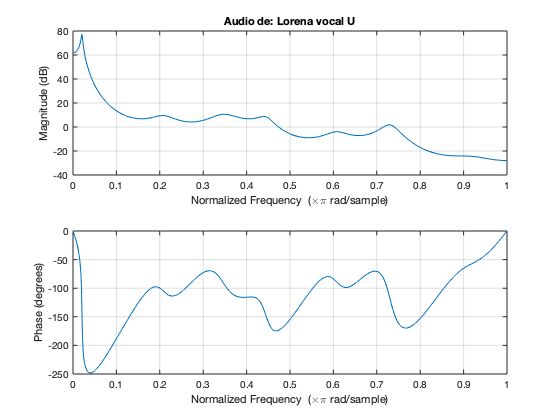

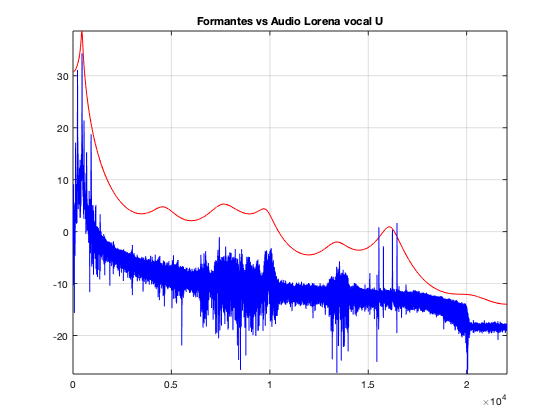

Formantes = 	1.0e+04 *

    1.6109    1.3382    0.9802    0.7592    0.4603    0.0377    0.0455


[Formantes] = Practica8(uL,uL_Fs, ' Lorena vocal U')

function [Formantes] = Practica8 (Audio, FS, Titulo)

Canal1 = Audio(:,1);
n = length(Canal1);
ventana = hamming(n).*Canal1;

grado = 20;
filtro = filter([1 0.63], [1],ventana);
A = lpc(filtro, grado);

[h, w] = freqz([1],A,n);

h = 10*log10(abs(h));
w = (w * (FS/(2*pi)));

raices = roots(A).';
[R,indices,basura] = unique(real(raices));
I= imag(raices);
I = I(indices);

[theta,rho] = cart2pol(R,I);

Theta = (FS/(2*pi)) * theta;
Ancho_Banda = (-1/2)*(FS/(2*pi))*log(rho);
Formantes = 0;

for i = 1:length(Ancho_Banda)
    if(Ancho_Banda(i)<400 & Theta(i)>90)
        if(Formantes(1) == 0)
            Formantes(1) = Theta(i);
        else
            Formantes(end+1)=Theta(i);
        end
    end
end

Titulo1 = strcat('Audio de:',Titulo);
figure %Grafica de Freqz
    freqz([1],A,n)
    title(Titulo1)

TF = 10*log10(abs(fft(Canal1, FS))); %fft
Titulo2 = strcat('Formantes vs Audio' ,Titulo);
figure %Formantes vs fft
    plot(w,h,'r')
    title(Titulo2)
    hold on
    grid on
    plot(TF,'b')
    axis([0, FS/2, -inf, inf])

end
